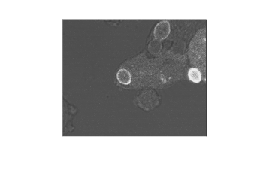

v = VideoReader("CellVideo.avi");

frame = read(v,82);

framegray = im2gray(frame);

imshow(framegray)

writer = VideoWriter("SegmentCellVideo.mp4");
open(writer)

for i=1 : v.NumFrames
    frame = read(v,i);
    [BW, maskedImage] = segmentImage(frame);
    
    bboxes = regionprops("table",BW,"BoundingBox");
    boxframe = insertObjectAnnotation(frame,"rectangle",bboxes.BoundingBox,"yeast");
    
    writeVideo(writer,boxframe);
end

close(writer)






function [BW,maskedImage] = segmentImage(X)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the Image Segmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 07-Jul-2023
%----------------------------------------------------

colorImg = X;
X = im2gray(colorImg);

% Threshold image with manual threshold
BW = im2gray(X) > 1.598000e+02;

% Fill holes
BW = imfill(BW, 'holes');

% Open mask with default
radius = 3;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Create masked image.
maskedImage = colorImg;
maskedImage(repmat(~BW,1,1,3)) = 0;
end

